# `inbasin` documentation

`inbasin` returns `true` for coordinates inside a given basin in the MEaSURES Antarctic Boundaries for IPY 2007-2009 from Satellite Radar dataset Version 2. 

The Antarctic Boundaries dataset is described on the NSIDC site [here](http://nsidc.org/data/NSIDC-0709). An overview of the tools in this AMT plugin can be found [here](Antbounds_Contents.html).

(For Zwally's basins instead use [`basinsps`](https://www.mathworks.com/matlabcentral/fileexchange/47639).)

<<plot_basins_demo.png>>

## Syntax

## Description

`tf = inbasin(lat,lon,basinDataset,basinName)` is `true` for all `lat,lon` points inside the polygon of the `basinName` inside a specified `basinDataset`. The optins for `basinDataset` are `'imbie'` or `'imbie refined'` and basin names can be determined by typing `plot_basins('demo')`. 

`tf = inbasin(x,y,basinDataset,basinName)` as above, but for input coordinates  `x,y` in polar stereographic meters (ps71 aka EPSG:3031)

## Example

Suppose you have a 25 km resolution grid, about 2000 km by 2000 km over West Antarctica. It looks like this: 

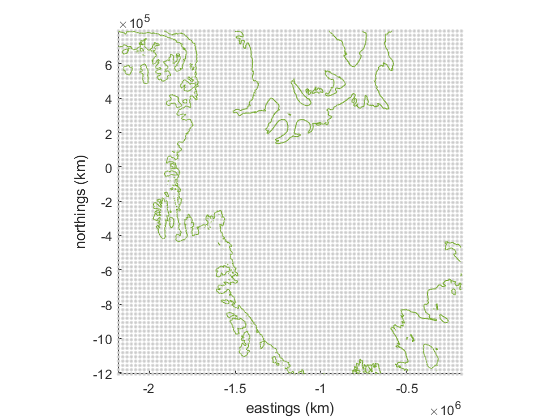

[lat,lon] = psgrid('west antarctica',2000,25); 

plotps(lat,lon,'.','color',0.8*[1 1 1]) 
axis tight 
antbounds('gl') 
xlabel 'eastings (km)' 
ylabel 'northings (km)'

And you want to know which of those grid points are drained by Thwaites Glacier. Here's the Thwaites Glacier basin outline: 

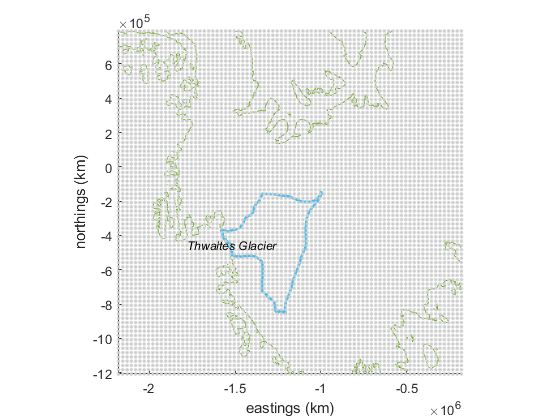

plot_basins('imbie refined','basin','Thwaites','linewidth',2)

% Add a nice label:
scarlabel('Thwaites Glacier','fontsize',9,'fontangle','italic')

The grid cells drained by Thwaites can be found by `inbasin` like this: 

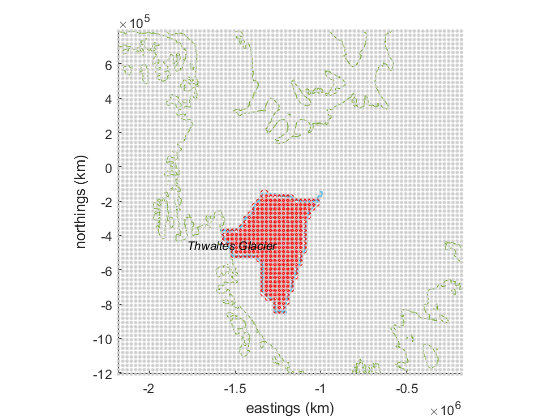

thwaites = inbasin(lat,lon,'imbie refined','thwaites'); 

% Plot Thwaites grid cells as red circles: 
plotps(lat(thwaites),lon(thwaites),'ro')

## Citing this dataset

If you use this dataset, please cite the following: 

- **The dataset:** Mouginot, J., B. Scheuchl, and E. Rignot. 2017. MEaSUREs Antarctic Boundaries for IPY 2007-2009 from Satellite Radar, Version 2. [Indicate subset used]. Boulder, Colorado USA. NASA National Snow and Ice Data Center Distributed Active Archive Center. [http://dx.doi.org/10.5067/AXE4121732AD](http://dx.doi.org/10.5067/AXE4121732AD). 

- **Literature citation:** Rignot, E., S. S. Jacobs, J. Mouginot, and B. Scheuchl. 2013. Ice-shelf melting around Antarctica, Science. 341. 266-270. [http://dx.doi.org/10.1126/science.1235798](http://dx.doi.org/10.1126/science.1235798). 

- **Antarctic Mapping Tools:** Greene, C. A., Gwyther, D. E., & Blankenship, D. D. Antarctic Mapping Tools for Matlab.  *Computers & Geosciences*. 104 (2017) pp.151-157. [doi:10.1016/j.cageo.2016.08.003](http://dx.doi.org/10.1016/j.cageo.2016.08.003).

## Author Info

This function and supporting documentation were written by [Chad A. Greene](http://www.chadagreene.com) of the University of Texas Institute for Geophysics (UTIG), May 2018. 